# AGNES

*Algorithme de clustering hiérarchique "ascendant". Nécessite d'avoir calculé les matrices de similarité.*

#### Principe

    Le clustering hiérarchique a l'avantage qu'il n'est pas nécessaire de définir le nombre de clusters à l'avance (on explore toutes les possibilités). Cependant, cela ne fait que repousser cette décision. Celle-ci peut se faire sur la base d'un dendrogramme (cela suppose de pouvoir bien visualiser le dendrogramme, ce qui sera plus aisé sur un petit jeu de données). On peut aussi évaluer les différentes partitions trouvées (une pour chaque valeur possible de nombre de clusters) avec une mesure telle que le coefficient de silhouette ou l'indice de Davies-Bouldin.

#### Inconvénients

    Par contre, sa complexité algorithmique est lourde. À chaque itération, pour décider quels clusters joindre, nous aurons besoin des distances deux à deux entre toutes les paires de points du jeu de données. Les calculer a un coût quadratique en temps de calcul ; les stocker, un coût quadratique en espace mémoire. Pour cette raison, le clustering hiérarchique est plus adapté aux échantillons contenant un *faible nombre d'individus*.

Les méthodes de lien (simple, complet, médian, moyen, centroid) permettent de garantir que les clusters sont bien séparés, car on prend en compte la distance entre les clusters. Cependant, elles ne garantissent pas que les clusters sont resserrés sur eux-mêmes (c'est la notion d'inertie intraclasse).

#### Méthode de Ward

    La méthode de Ward consiste à regrouper les classes de façon que l'augmentation de l'inertie interclasse soit maximale, ou, ce qui revient au même d'après le [théorème de Huygens](https://fr.wikipedia.org/wiki/Th%C3%A9or%C3%A8me_de_Huygens), de façon que l'augmentation de l'inertie intraclasse soit minimum. 

Concrètement à chaque itération, c'est-à-dire à chaque fois que 2 clusters sont regroupés en 1, l'algorithme cherche à minimiser l'augmentation d'inertie intraclasse due au regroupement des 2 clusters. 

*Par défaut, on préfère en général utiliser la méthode de Ward.*

## I. Accès dossier et choix essai

clear
Type = "DCMS1N";
Materiau = '3135';
Eprouvette ='0';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## II. Paramètres de clustering

agglo = "single";
coupure =0.8;
nbre_clust = 8600;
event = false;
WF_condense = true;
 

if WF_condense == 1
    Cor1 = Corc1;
    Cor2 = Corc2;
end

% Création d'une variable CLUSTER dans HDD
HDD = addvars(HDD,zeros(height(HDD),1),'NewVariableNames','CLUSTER');
% HDD.Properties.VariableNames{'Var25'} = 'CLUSTER';

if event == 1
    Cor1 = Cor1_events;
    Cor2 = Cor2_events;
end

% ---- Pré-traitement ------
% Ajout d'une dernière ligne et remplissage de la diagonale
Cor1 = [Cor1;zeros(1,length(Cor1))];
for i = 1:length(Cor1)
    Cor1(i,i) = 1;
end
Cor2 = [Cor2;zeros(1,length(Cor2))];
for i = 1:length(Cor2)
    Cor2(i,i) = 1;
end

% Passage de matrice de similarité et dissimilarité
Cor2 = -Cor2+1;
Cor1 = -Cor1+1;

% % Arrangement de Cor en vecteur en ordre (2,1), (3,1), ..., (m,1), (3,2), ..., (m,2), ..., (m,m – 1))
CorVec1 = Cor1(1,2:end);
for i = 2:(size(Cor1,2)-1)
    CorVec1 = [CorVec1, Cor1(i,(i+1):end)];
end
% CorVec1 = reshape(Cor1', 1, []);
CorVec2 = Cor2(1,2:end);
for i = 2:(size(Cor2,2)-1)
    CorVec2 = [CorVec2, Cor2(i,(i+1):end)];
end
clear Cor1 Cor2

% Constitution de l'arbre de séparation
tree1 = linkage(CorVec1,agglo);
tree2 = linkage(CorVec2,agglo);

## III. Construction du dendrogramme

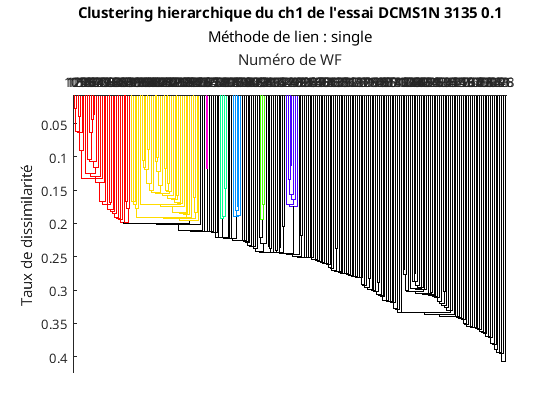

dendro = true;

if dendro == 1
    figure();
    dendrogram(tree1,nbre_clust,"ColorThreshold",(1-coupure),"Orientation",'bottom');
    xlabel("Numéro de WF");
    ylabel("Taux de dissimilarité");
    title(strcat("Clustering hierarchique du ch1 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
    subtitle(strcat("Méthode de lien : ",agglo));
    if event == 1
        subtitle(strcat("Events uniquement, Méthode de lien : ",agglo));
    end
%     ylim([0 0.6]);
end

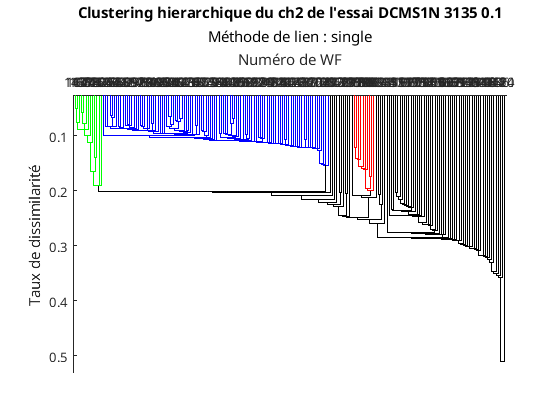

if dendro == 1
    figure();
    dendrogram(tree2,nbre_clust,"ColorThreshold",(1-coupure),'Orientation','bottom');
    xlabel("Numéro de WF");
    ylabel("Taux de dissimilarité");
    title(strcat("Clustering hierarchique du ch2 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
    subtitle(strcat("Méthode de lien : ",agglo));
    if event == 1
        subtitle(strcat("Events uniquement, Méthode de lien : ",agglo));
    end
%     ylim([0 0.6]);
end

## IV. Extraction de clusters

methode = "CutOff";
seuil =0.8;
% depth = 1; cf doc pour infos sur inconsistency 
nbre_cl = 5;
 

% Suppression de la variable CLUSTER existante
if exist("CLUSTER","var");
    HDD = removevars(HDD,'CLUSTER');
end

if methode == "MaxClust"
    % Constitution des clusters suivant les paramètres
    Clust1 = cluster(tree1,'maxclust',nbre_cl);
    Clust2 = cluster(tree2,'maxclust',nbre_cl);    
end
if methode == "CutOff"
    % Constitution des clusters suivant les paramètres
    Clust1 = cluster(tree1,'cutoff',(1-seuil),"criterion","distance");
    Clust2 = cluster(tree2,'cutoff',(1-seuil),"criterion","distance");
end

% Concatenation des 2 listes de clusters
Clust = cat(1,(Clust1.*2-1),Clust2.*2);
% Création de la variable CLUSTER et assignation des clusters au HDD 
HDD = sortrows(HDD,"CH");
if event == 1 
    idx = find(isnan(HDD.LOC)==0); % Récupération des indices des hits localisés
else
    idx = find(isnan(HDD.Time)==0); % Récupération de tous les indices
end
HDD.CLUSTER(idx) = Clust;

###         1. Statistiques clusters

*              ---> Statistiques et graphs pertinents à ajouter *

if methode == "CutOff"    
    Nombre_total_Clusters = length(unique(Clust))
    Nombre_Clust_ch1 = length(unique(Clust1))
    Nombre_Clust_ch2 = length(unique(Clust2))
end

Nombre_total_Clusters = 228

Nombre_Clust_ch1 = 154

Nombre_Clust_ch2 = 74

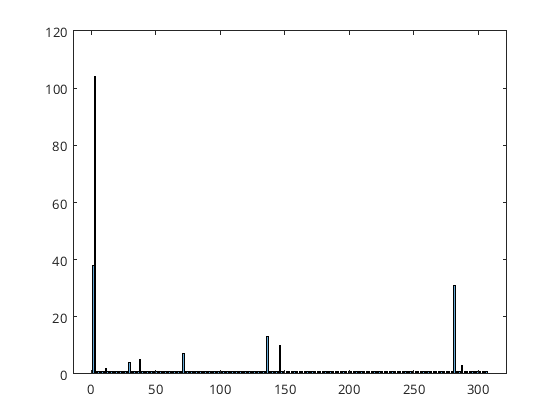

if methode == "MaxClust"
    Seuil_pour_ce_nombre_de_clusters_ch1 = 1-tree1(end-nbre_cl+1,3)
    Seuil_pour_ce_nombre_de_clusters_ch2 = 1-tree2(end-nbre_cl+1,3)
end
histogram(Clust,'BinWidth',1);

###       2. Affichage des clusters

#### A. Tous les clusters filtrés       

 Choix des variables :

ParaX = "CYCLES";
ParaY = "PARA1";
TDDpara1 = true;
 
nbre_WF_min = 1;

% Filtrage des clusters trop petits
ClustF = Clust;
Num_max_cluster = max(ClustF)

Num_max_cluster = 307

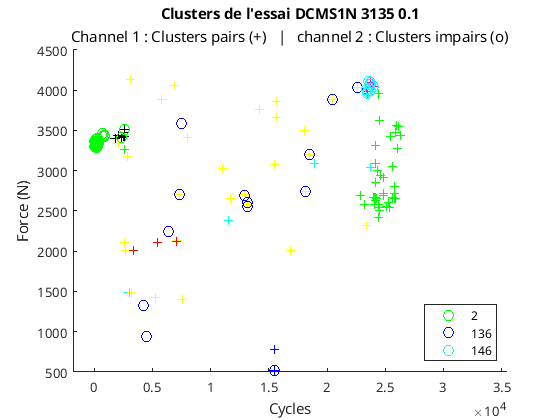

for a = 1:Num_max_cluster
    ind = find(ClustF==a);
    if length(ind) <= nbre_WF_min
        for i = ind
            ClustF(i) = nan;
        end
    end
end
% Réimport des clusters dans HDD
HDD = sortrows(HDD,"CH");
ch1nbre = length(unique(find(HDD.CH==1)));
HDD.CLUSTER(idx) = ClustF;

figure();
hold on

%------- Affichage des cycles et HDD si besoin
% if TDDpara1 == 1
%     plot(TDD.Time,TDD.PARA1,'y-',"DisplayName",'TDD');
% end
% plot(HDD.(ParaX),HDD.(ParaY),'r.','DisplayName','HDD');
HDD.CLUSTER(find(HDD.CLUSTER==0)) = nan;

%------- Affichage des clusters filtrés du CH1 (+) puis de ceux du CH2 (.) 
gscatter(HDD.(ParaX)(1:ch1nbre),HDD.(ParaY)(1:ch1nbre),HDD.CLUSTER(1:ch1nbre),'gbcmkyr','+',6);
gscatter(HDD.(ParaX)((ch1nbre+1):end),HDD.(ParaY)((1+ch1nbre):end),HDD.CLUSTER((1+ch1nbre):end),'gbcmkyr','o',8);
% gscatter(HDD.(ParaX),HDD.(ParaY),HDD.CLUSTER,'gbcmkyr','+o',6);

xlabel(HDD.Properties.VariableDescriptions{ParaX});
ylabel(HDD.Properties.VariableDescriptions{ParaY});
legend("Location","southeast");
title(strcat("Clusters de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
subtitle("Channel 1 : Clusters pairs (+)   |   channel 2 : Clusters impairs (o)");
hold off

#### B. Un cluster au choix

     Choix des variables :

ParaX = "RISE";
ParaY = "AMP";
TDDpara1 = false;

    Choix du cluster à afficher : 

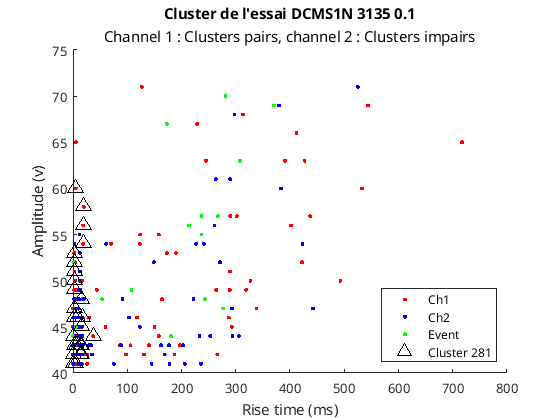

Clust_affi = 281;
 


% Réimport des clusters dans HDD (filtrés dans la section précédente)
HDD = sortrows(HDD,"CH");
HDD.CLUSTER(idx) = Clust;

figure();
nbre_CLUSTER = max(max(HDD.CLUSTER));
if TDDpara1 == 1
    plot(TDD.Time,TDD.PARA1,'y-',"DisplayName",'TDD');
end
hold on
% Affichage HDD
plot(HDD.(ParaX),HDD.(ParaY),'r.','DisplayName','Ch1');
ind = find(HDD.CH==2);
plot(HDD.(ParaX)(ind),HDD.(ParaY)(ind),'b.','DisplayName','Ch2');
ind = find(HDD.LOC>0);
plot(HDD.(ParaX)(ind),HDD.(ParaY)(ind),'g.','DisplayName','Event');

% Affichage du cluster
ind = find(HDD.CLUSTER==Clust_affi);
plot(HDD.(ParaX)(ind),HDD.(ParaY)(ind),'^',"MarkerSize",10,"Color",'k','DisplayName',strcat('Cluster'," ",string(Clust_affi)));        

title(strcat("Cluster de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
subtitle("Channel 1 : Clusters pairs, channel 2 : Clusters impairs");
xlabel(HDD.Properties.VariableDescriptions{ParaX});
ylabel(HDD.Properties.VariableDescriptions{ParaY});
legend("Location","southeast");
hold off

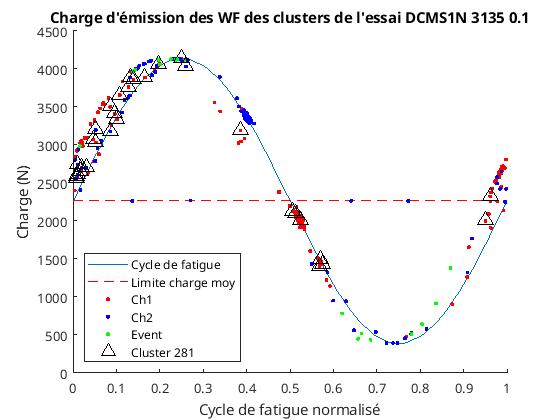



%--------------------- Partie affichage de la position cyclique 
dte = mean(Cycle(2:end,2)-Cycle(1:(end-1),2));
[x0, maxi, mini] = depart_cycle(TDD,1/dte);


moy = (maxi+mini)/2;
Dcharge = maxi-moy;
x = (0:0.01:1);
c = [mini maxi];
figure();
hold on; 
plot(x,Dcharge*sin(2*pi*x+6*pi/4+pi/2)+moy);
plot([0 1],[moy moy],'r--');
ylabel('Charge (N)');
xlabel("Cycle de fatigue normalisé");
title(strcat("Charge d'émission des WF des clusters de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
labels = {'Cycle de fatigue',"Limite charge moy"};
legend(labels,"Location","southwest");
xlim([0 1]);

% Décalage cycle pour affichage
for i = 1:height(HDD)
    cycles_decal(i) = HDD.CYCLES(i)-1/4;
end
% Affichage HDD
plot(cycles_decal-fix(cycles_decal),HDD.PARA1,'r.','DisplayName','Ch1');
ind = find(HDD.CH==2);
plot(cycles_decal(ind)-fix(cycles_decal(ind)),HDD.PARA1(ind),'b.','DisplayName','Ch2');
ind = find(HDD.LOC>0);
plot(cycles_decal(ind)-fix(cycles_decal(ind)),HDD.PARA1(ind),'g.','DisplayName','Event');

% % Affichage du cluster
ind = find(HDD.CLUSTER==Clust_affi);
Cy = (cycles_decal(ind)-fix(cycles_decal(ind)));
plot(Cy,HDD.PARA1(ind),'^',"MarkerSize",10,"Color",'k','DisplayName',strcat('Cluster'," ",string(Clust_affi)));

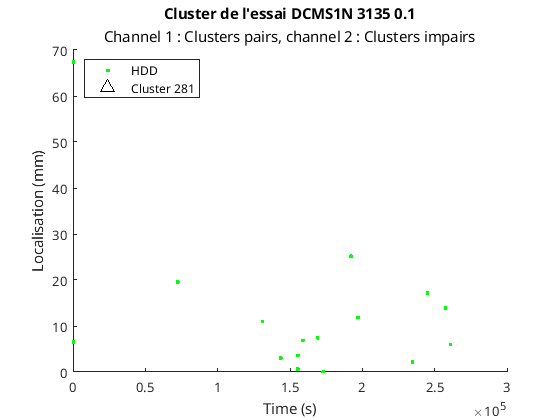

figure();
hold on
plot(HDD.Time,HDD.LOC,'g.','DisplayName','HDD');

% Affichage du cluster
ind = find(HDD.CLUSTER==Clust_affi);
plot(HDD.Time(ind),HDD.LOC(ind),'^',"MarkerSize",10,"Color",'k','DisplayName',strcat('Cluster'," ",string(Clust_affi)));        

title(strcat("Cluster de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
subtitle("Channel 1 : Clusters pairs, channel 2 : Clusters impairs");
xlabel(HDD.Properties.VariableDescriptions{'Time'});
ylabel(HDD.Properties.VariableDescriptions{'LOC'});
legend("Location","northwest");
hold off

## Localisation relative

Si events uniquement

if event == 1
    
    
    
    
    
    
    
end

% % ------ Pour essai C6C0SN ---------
% 
% 
% % Arrangement de Cor en vecteur en ordre (2,1), (3,1), ..., (m,1), (3,2), ..., (m,2), ..., (m,m – 1))
% Corr3 = -Cor3+1;
% CorVec3 = Corr3(2,3:end);
% for i = 3:(size(Corr3,2)-1)
%     CorVec3 = [CorVec3, Corr3(i,(i+1):end)];
% end
% tree = linkage(CorVec3,agglo);
% % leafOrder = sort(tree(:,2));
% figure();
% dendrogram(tree,0,"ColorThreshold",(1-coupure)*max(tree(:,3)),'Orientation','bottom');
% xlabel("Numéro de WF");
% ylabel("Taux de dissimilarité");
% title(strcat("Clustering hierarchique du ch3 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
% subtitle(strcat("Méthode de lien : ",agglo));
% 
% 
% % Arrangement de Cor en vecteur en ordre (2,1), (3,1), ..., (m,1), (3,2), ..., (m,2), ..., (m,m – 1))
% Corr4 = -Cor4+1;
% CorVec4 = Corr4(2,3:end);
% for i = 3:(size(Corr4,2)-1)
%     CorVec4 = [CorVec4, Corr4(i,(i+1):end)];
% end
% tree = linkage(CorVec4,agglo);
% % leafOrder = sort(tree(:,2));
% figure();
% dendrogram(tree,0,"ColorThreshold",(1-coupure)*max(tree(:,3)),'Orientation','bottom');
% xlabel("Numéro de WF");
% ylabel("Taux de dissimilarité");
% title(strcat("Clustering hierarchique du ch4 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
% subtitle(strcat("Méthode de lien : ",agglo));
% 
% 
% % Arrangement de Cor en vecteur en ordre (2,1), (3,1), ..., (m,1), (3,2), ..., (m,2), ..., (m,m – 1))
% Corr5 = -Cor5+1;
% CorVec5 = Corr5(2,3:end);
% for i = 3:(size(Corr5,2)-1)
%     CorVec5 = [CorVec5, Corr5(i,(i+1):end)];
% end
% tree = linkage(CorVec5,agglo);
% % leafOrder = sort(tree(:,2));
% figure();
% dendrogram(tree,0,"ColorThreshold",(1-coupure)*max(tree(:,3)),'Orientation','bottom');
% xlabel("Numéro de WF");
% ylabel("Taux de dissimilarité");
% title(strcat("Clustering hierarchique du ch5 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
% subtitle(strcat("Méthode de lien : ",agglo));
% 
% 
% % Arrangement de Cor en vecteur en ordre (2,1), (3,1), ..., (m,1), (3,2), ..., (m,2), ..., (m,m – 1))
% Corr6 = -Cor6+1;
% CorVec6 = Corr6(2,3:end);
% for i = 3:(size(Corr6,2)-1)
%     CorVec6 = [CorVec6, Corr6(i,(i+1):end)];
% end
% tree = linkage(CorVec6,agglo);
% % leafOrder = sort(tree(:,2));
% figure();
% dendrogram(tree,0,"ColorThreshold",(1-coupure)*max(tree(:,3)),'Orientation','bottom');
% xlabel("Numéro de WF");
% ylabel("Taux de dissimilarité");
% title(strcat("Clustering hierarchique du ch6 de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
% subtitle(strcat("Méthode de lien : ",agglo));
